# Vacchini Edoardo 467102

Partendo dai dati puliti si può ora partire con la fase di identificazione del modello. Questa verrà fatta considerando i seguenti modelli:

- **Modello cubico**: si tratta di un modello di riferimento del caso. Si spezza l'intervallo di dati in 3 e si identifica un modello cubico per l'intervallo tra la *cut-in wind speed* e la *cut-out wind speed*, ovvero dove non è presente la saturazione. 

- **Modello a doppio esponenziale**: prende in considerazione la curva fino alla cutout speed.

- **Funzione logistica**: grazie alla sua forma a sigmoide si potrebbe prestarsi bene

- **Rete Neurale**: 

close all; clc; clear;
turbines = readtable('../datasets/clean_dataset.csv');
rawdata = readtable('../datasets/dataset.csv');

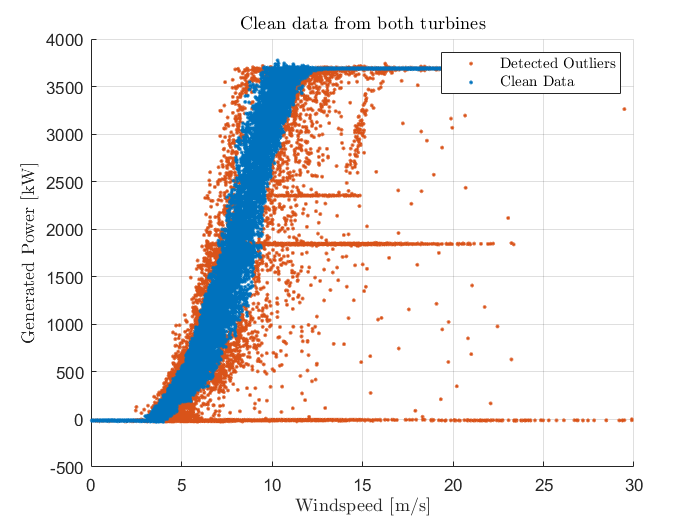

figure;
scatter([rawdata.ws; rawdata.ws], [rawdata.turbine_power1; rawdata.turbine_power10], '.', 'MarkerEdgeColor', '#D95319');
hold on;
scatter(turbines.windspeed, turbines.power, '.', 'MarkerEdgeColor', '#0072BD');
grid on;
title('Clean data from both turbines', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Generated Power [kW]', "Interpreter", 'latex');
legend("Detected Outliers", "Clean Data", "Interpreter", 'latex');

Per prima cosa preparo i dati di identificazione e quelli di validazione spezzando in due set il dataset, uno di training e uno di validazione.

trainingPercentage = 0.8;

trainingSet = turbines(randperm(size(turbines, 1), floor(trainingPercentage * size(turbines, 1))), :);
validationSet = setdiff(turbines, trainingSet);

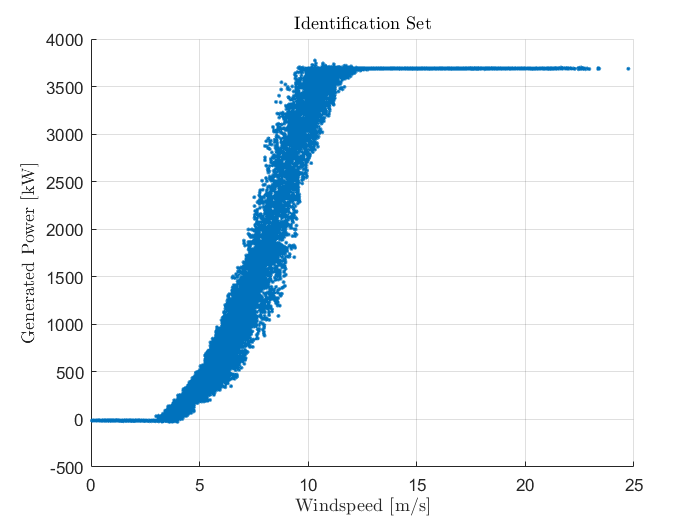

figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
grid on;
title('Identification Set', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Generated Power [kW]', "Interpreter", 'latex');

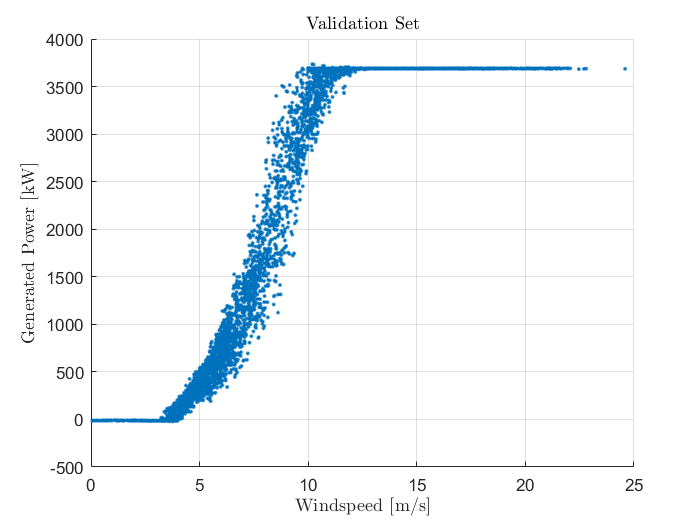


figure;
scatter(validationSet.windspeed, validationSet.power, '.');
grid on;
title('Validation Set', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Generated Power [kW]', "Interpreter", 'latex');

### Modello Benchmark

Il modello benchmark è costuito da una semplice funzione cubica nell'intervallo incluso tra le velocità di *cut-in* e di *cut-out*.


$$P\left(v\right)=\frac{1}{2}\rho {\;}_{\textrm{air}} A\;v^{3\;}$$


Dove $\rho_{\textrm{air}}$ è la densità dell'aria e $A$ è l'area della spazzata, ovvero la superficie coperta dalla pala di raggio $r=65m$.

cutin_windspeed = 3;
cutout_windspeed = 12;

datainrange = trainingSet(trainingSet.windspeed > cutin_windspeed & trainingSet.windspeed <= cutout_windspeed, :);
[theta, sigma] = lscov(datainrange.windspeed.^3, datainrange.power);
Y_Hat = datainrange.windspeed.^3 * theta;

Nella sezione di saturazione per completare il modello su tutto l'intervallo di velocità del vento, uso il valore medio delle saturazioni vere e lo applico da quando la curva cubica supera il livello di saturazione;

saturationValue = mean(trainingSet(trainingSet.windspeed > 12 , :).power);

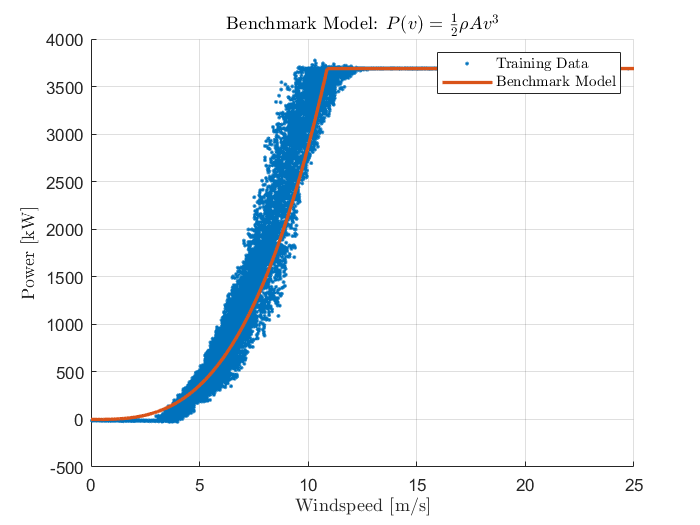

density = 0.01;
saturationWindspeed = density * floor(((saturationValue / theta) ^ (1/3))*(1/density));
windspeedGrid = [0 : density : 25]';

figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
hold on;
grid on;
plot(windspeedGrid, benchmark_model(windspeedGrid, theta, saturationWindspeed, saturationValue), "LineWidth", 2);
title('Benchmark Model: $P(v) = \frac{1}{2}\rho Av^3$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Power [kW]', "Interpreter", 'latex');
legend("Training Data", "Benchmark Model", "Interpreter", 'latex');

Le predizioni sui dati di validazione:

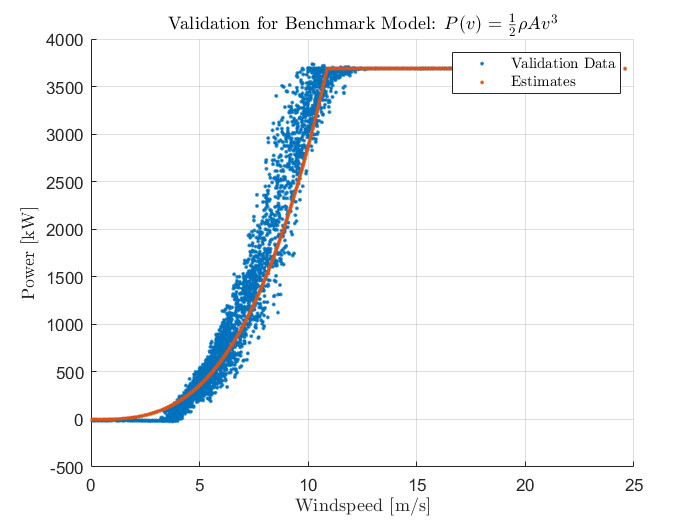

Y_Hat_validation = benchmark_model(validationSet.windspeed, theta, saturationWindspeed, saturationValue);

figure;
scatter(validationSet.windspeed, validationSet.power, '.');
hold on;
grid on;
scatter(validationSet.windspeed, Y_Hat_validation, '.');
title('Validation for Benchmark Model: $P(v) = \frac{1}{2}\rho Av^3$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Power [kW]', "Interpreter", 'latex');
legend("Validation Data", "Estimates", "Interpreter", 'latex');

Goodness of fit:

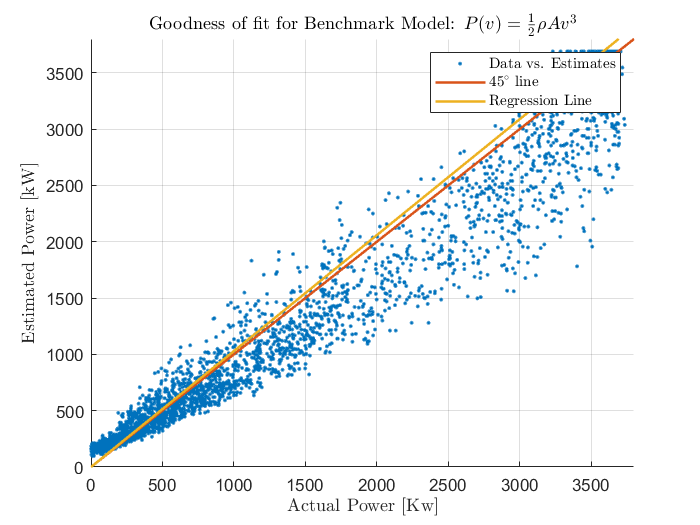

thetaGOF = lscov(Y_Hat_validation, validationSet.power);

figure;
scatter(validationSet.power, Y_Hat_validation, '.');
grid on;
hold on;
plot([0, 3800], [0,3800], 'LineWidth', 1.5);
plot([0, 3800], thetaGOF*[0,3800], 'LineWidth', 1.5);
axis([0, 3800, 0, 3800]);
title('Goodness of fit for Benchmark Model: $P(v) = \frac{1}{2}\rho Av^3$', 'Interpreter', 'latex');
xlabel('Actual Power [Kw]', "Interpreter", 'latex');
ylabel('Estimated Power [kW]', "Interpreter", 'latex');
legend("Data vs. Estimates", "$45^{\circ}$ line", "Regression Line", "Interpreter", 'latex');

benchmarkModel.parameters = theta;
benchmarkModel.standardDeviation = sigma;

benchmarkModel.SSR = sum((datainrange.power - Y_Hat).^2);
benchmarkModel.MSE = (1/length(Y_Hat)) * benchmarkModel.SSR;

benchmarkModel.FPE = ((length(Y_Hat) + length(theta))/(length(Y_Hat) - length(theta))) * benchmarkModel.SSR ;
benchmarkModel.AIC = (2*length(theta) / length(Y_Hat)) * log(benchmarkModel.SSR);
benchmarkModel.MDL = (log(length(Y_Hat))*length(theta) / length(Y_Hat)) * log(benchmarkModel.SSR);

benchmarkModel.ValidationSSR = sum((validationSet.power - Y_Hat_validation).^2);
benchmarkModel.ValidationMSE = benchmarkModel.SSR / length(Y_Hat_validation);

benchmarkModel.WMAPE = sum(abs(validationSet.power - Y_Hat_validation)) / sum(abs(validationSet.power));
benchmarkModel.NRMSE = sqrt(benchmarkModel.ValidationMSE / (max(validationSet.power) - min(validationSet.power)));

### Modelli cubici

Un modello di riferimento è quello cubico, con cui si modellizza il tratto crescente con un modello:


$$P\left(v\right)=\theta_1 +\theta_2 v+\theta_3 v^{2\;} +\theta_4 v^3$$


cutin_windspeed = 1.5;
cutout_windspeed = 12.5;

datainrange = trainingSet(trainingSet.windspeed < cutout_windspeed & trainingSet.windspeed > cutin_windspeed, :);

PHI = [ones(length(datainrange.windspeed), 1), datainrange.windspeed, datainrange.windspeed.^2, datainrange.windspeed.^3];
[theta, sigma] = lscov(PHI, datainrange.power);
Y_Hat = PHI*theta;

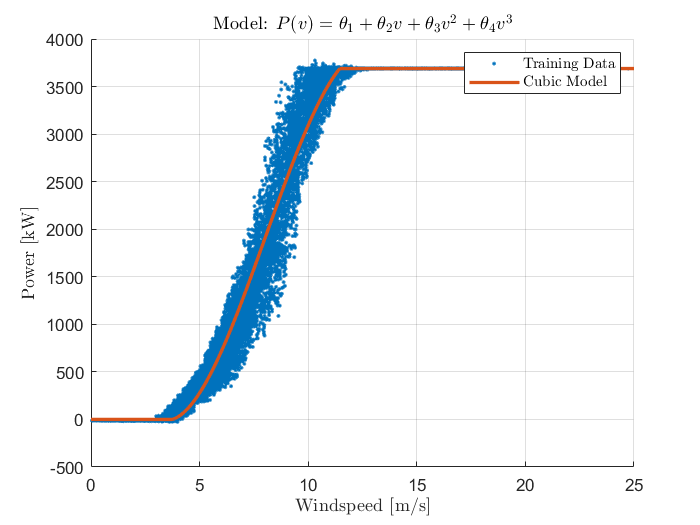

density = 0.01;
windspeedGrid = [cutin_windspeed : density : cutout_windspeed]';
PHIGrid = [ones((cutout_windspeed - cutin_windspeed)/density + 1, 1), windspeedGrid, windspeedGrid.^2, windspeedGrid.^3];
Y_Hat_grid = PHIGrid * theta;

cutoutTDF = min(windspeedGrid(Y_Hat_grid >= saturationValue));
cutinTDF = max(windspeedGrid(Y_Hat_grid <= 0 ));
windspeedGrid = [0 : density : 25]';

figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
hold on;
plot(windspeedGrid, thirdDegreeFull_model(windspeedGrid, theta, cutoutTDF, saturationValue, cutinTDF), 'LineWidth',2);
grid on;
title('Model: $P(v) = \theta_1 + \theta_2 v + \theta_3 v^2 + \theta_4 v^3$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Power [kW]', "Interpreter", 'latex');
legend("Training Data", "Cubic Model", "Interpreter", 'latex');

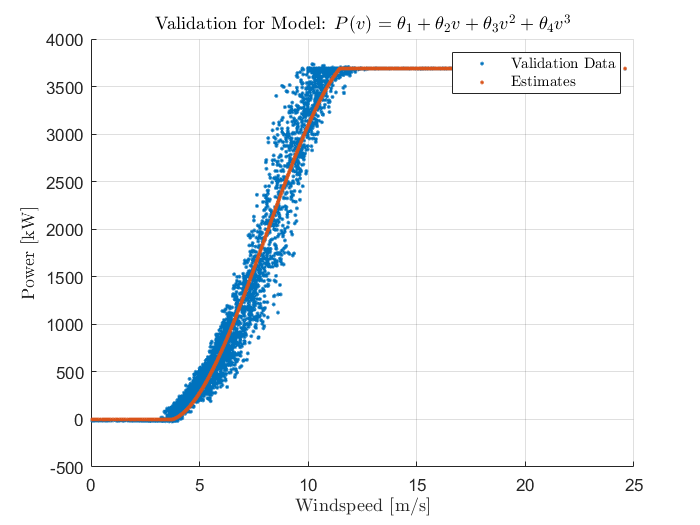

Y_Hat_validation = thirdDegreeFull_model(validationSet.windspeed, theta, cutoutTDF, saturationValue, cutinTDF);

figure;
scatter(validationSet.windspeed, validationSet.power, '.');
hold on;
scatter(validationSet.windspeed, Y_Hat_validation, '.');
grid on;
title('Validation for Model: $P(v) = \theta_1 + \theta_2 v + \theta_3 v^2 + \theta_4 v^3$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Power [kW]', "Interpreter", 'latex');
legend("Validation Data", "Estimates", "Interpreter", 'latex');

Goodness of fit:

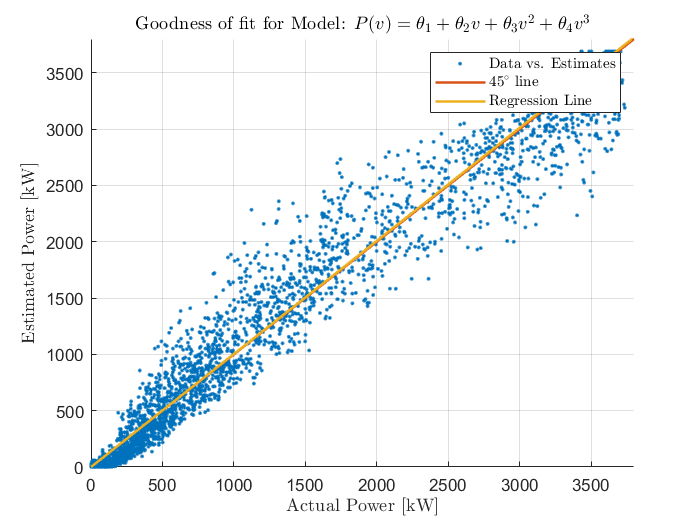

thetaGOF = lscov(Y_Hat_validation, validationSet.power);

figure;
scatter(validationSet.power, Y_Hat_validation, '.');
grid on;
hold on;
plot([0, 3800], [0,3800], 'LineWidth', 1.5);
plot([0, 3800], [0, thetaGOF*3800], 'LineWidth', 1.5);
axis([0, 3800, 0, 3800]);
title('Goodness of fit for Model: $P(v) = \theta_1 + \theta_2 v + \theta_3 v^2 + \theta_4 v^3$', 'Interpreter', 'latex');
xlabel('Actual Power [kW]', "Interpreter", 'latex');
ylabel('Estimated Power [kW]', "Interpreter", 'latex');
legend("Data vs. Estimates", "$45^{\circ}$ line", "Regression Line", "Interpreter", 'latex');

cubicModel_fourth.parameters = theta;
cubicModel_fourth.standardDeviation = sigma;

cubicModel_fourth.SSR = sum((datainrange.power - Y_Hat).^2);
cubicModel_fourth.MSE = (1/length(Y_Hat))*cubicModel_fourth.SSR;

cubicModel_fourth.FPE = ((length(Y_Hat) + length(theta))/(length(Y_Hat) - length(theta))) * cubicModel_fourth.SSR;
cubicModel_fourth.AIC = ((2*length(theta))/(length(Y_Hat)))*log(cubicModel_fourth.SSR);
cubicModel_fourth.MDL = ((log(length(Y_Hat))*length(theta)) / (length(Y_Hat))) * log(cubicModel_fourth.SSR);

cubicModel_fourth.ValidationSSR = sum((validationSet.power - Y_Hat_validation).^2);
cubicModel_fourth.ValidationMSE = cubicModel_fourth.ValidationSSR / length(Y_Hat_validation);

cubicModel_fourth.WMAPE = sum(abs(validationSet.power - Y_Hat_validation))/sum(abs(validationSet.power));
cubicModel_fourth.NRMSE = sqrt(cubicModel_fourth.ValidationMSE / (max(validationSet.power) - min(validationSet.power)));

Prendo in considerazione modelli cubici di ordini diversi:


$$P\left(v\right)=\theta_1 v+\theta_2 v^{2\;} +\theta_3 v^3$$


PHI = [datainrange.windspeed, datainrange.windspeed.^2, datainrange.windspeed.^3];
[theta, sigma] = lscov(PHI, datainrange.power);
Y_Hat = PHI*theta;

density = 0.01;
windspeedGrid = [cutin_windspeed : density : cutout_windspeed]';
PHIGrid = [windspeedGrid, windspeedGrid.^2, windspeedGrid.^3];
Y_Hat_grid = PHIGrid * theta;

cutinTD = max(windspeedGrid(Y_Hat_grid <= 0));
cutoutTD =  min(windspeedGrid(Y_Hat_grid >= saturationValue));

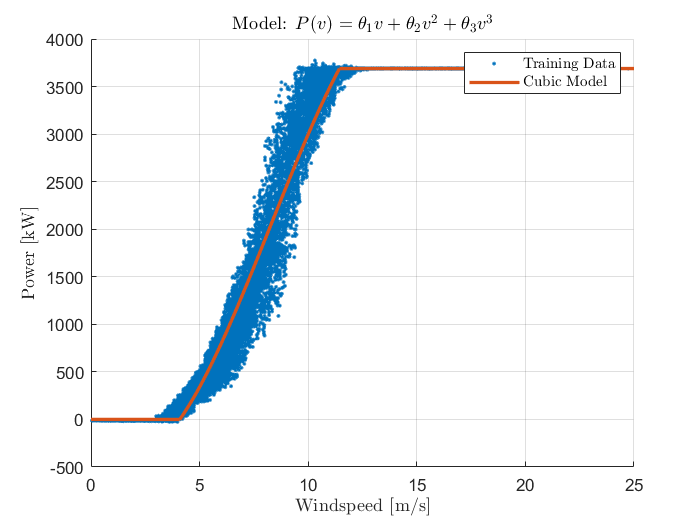

windspeedGrid = [0 : density : 25]';

figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
hold on;
plot(windspeedGrid, thirdDegree_model(windspeedGrid, theta, cutoutTD, saturationValue, cutinTD), "LineWidth", 2);
grid on;
title('Model: $P(v) = \theta_1 v + \theta_2 v^2 + \theta_3 v^3$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Power [kW]', "Interpreter", 'latex');
legend("Training Data", "Cubic Model", "Interpreter", 'latex');

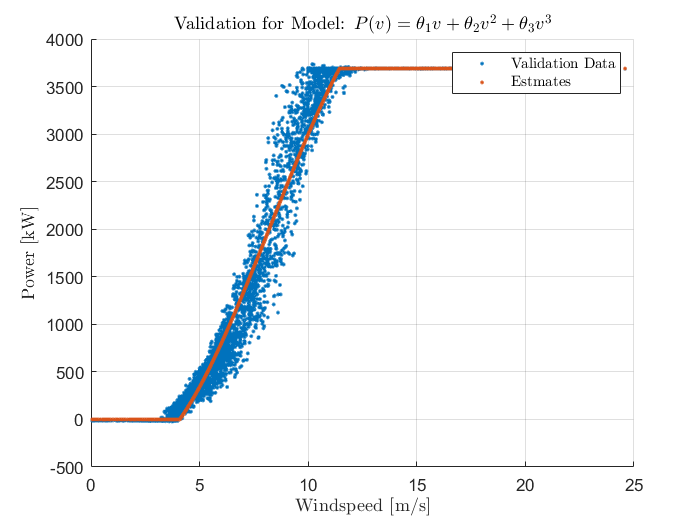

Y_Hat_validation = thirdDegree_model(validationSet.windspeed, theta, cutoutTD, saturationValue, cutinTD);

figure;
scatter(validationSet.windspeed, validationSet.power, '.');
hold on;
scatter(validationSet.windspeed, Y_Hat_validation, '.');
grid on;
title('Validation for Model: $P(v) = \theta_1 v + \theta_2 v^2 + \theta_3 v^3$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Power [kW]', "Interpreter", 'latex');
legend("Validation Data", "Estmates", "Interpreter", 'latex');

Goodness of fit:

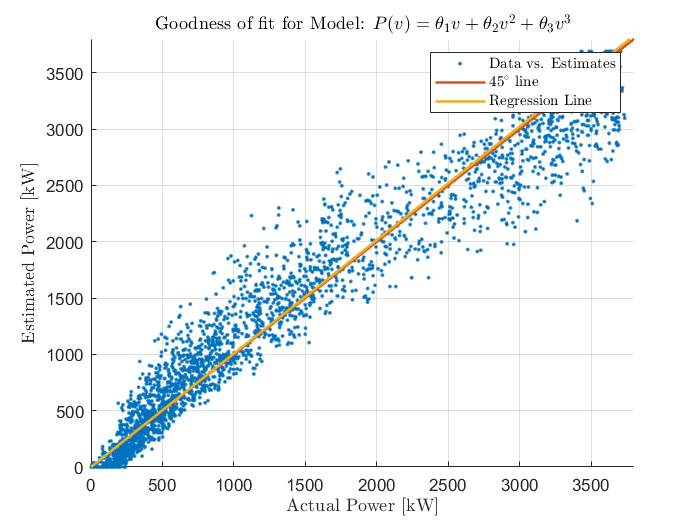

thetaGOF = lscov(Y_Hat_validation, validationSet.power);

figure;
scatter(validationSet.power, Y_Hat_validation, '.');
grid on;
hold on;
plot([0, 3800], [0,3800], 'LineWidth', 1.5);
plot([0, 3800], [0,thetaGOF*3800], 'LineWidth', 1.5);
axis([0, 3800, 0, 3800]);
title('Goodness of fit for Model: $P(v) = \theta_1 v + \theta_2 v^2 + \theta_3 v^3$', 'Interpreter', 'latex');
xlabel('Actual Power [kW]', "Interpreter", 'latex');
ylabel('Estimated Power [kW]', "Interpreter", 'latex');
legend("Data vs. Estimates", "$45^{\circ}$ line", "Regression Line", "Interpreter", 'latex');

cubicModel_third.parameters = theta;
cubicModel_third.standardDeviation = sigma;

cubicModel_third.SSR = sum((datainrange.windspeed - Y_Hat).^2);
cubicModel_third.MSE = cubicModel_third.SSR / length(Y_Hat);

cubicModel_third.FPE = ((length(Y_Hat) + length(theta))/(length(Y_Hat) - length(theta))) * cubicModel_third.SSR;
cubicModel_third.AIC = ((2*length(theta))/(length(Y_Hat)))*log(cubicModel_third.SSR);
cubicModel_third.MDL = ((log(length(Y_Hat))*length(theta)) / (length(Y_Hat))) * log(cubicModel_third.SSR);

cubicModel_third.ValidationSSR = sum((validationSet.power - Y_Hat_validation).^2);
cubicModel_third.ValidationMSE = cubicModel_third.ValidationSSR / length(Y_Hat_validation);

cubicModel_third.WMAPE = sum(abs(validationSet.power - Y_Hat_validation)) / sum(abs(validationSet.power));
cubicModel_third.NRMSE = sqrt(cubicModel_third.MSE / (max(validationSet.power) - min(validationSet.power)));

## Modello a doppio esponenziale

Il secondo tipo di modello preso in consideraizone è quello a doppio esponenziale. Il doppio esponenziale ha la forma classica del sigmoide che presenta anche la curva di potenza classica. Il modello a doppio esponenziale è della forma:


$$P(v) = e^{-e^ {\theta_1 v + \theta_2 v^2 + \theta_3 v^3}}$$
  

Attraverso un estrazione di due logaritmi naturali è possibile ricondurre a un modello lineare nei parametri:


$$log(-log(P(v))) = \theta_1 v + \theta_2 v^2 + \theta_3 v^3$$


In questo caso l'intervallo di valori presi in considerazione è quello al di sotto della velocità di cut-out del vento. Necessario prendere solo i valori di potenza strettamente positivi a causa della presenza del logaritmo. Inoltre $P\left(v\right)$ deve essere la funzione normalizzata, ovvero con valori $P\left(v\right)\in \left\lbrack 0,1\right\rbrack$, siccome il meno logaritmo deve essere definito.

cutout_windspeed = 15;
cutin_windspeed = 3;

datainrange = trainingSet(trainingSet.power > 0 & trainingSet.windspeed < cutout_windspeed , :);
scale = max(datainrange.power);
logData = [datainrange.windspeed, log( - log( (1/scale) * datainrange.power))];

PHI = [logData(:,1), logData(:,1).^2, logData(:,1).^3];
[theta, sigma] = lscov(PHI, logData(:,2));
logY = PHI * theta;
Y_Hat = scale * exp(-exp(logY));

density = 0.01;
windspeedGrid = [0.1 : density : 15]';
PHIGrid = [windspeedGrid, windspeedGrid.^2, windspeedGrid.^3];
Y_Hat_grid = scale*exp(-exp(PHIGrid * theta));

cutoutDE = min(logData(Y_Hat >= saturationValue, 1));
cutinDE = windspeedGrid( Y_Hat_grid == min(Y_Hat_grid));

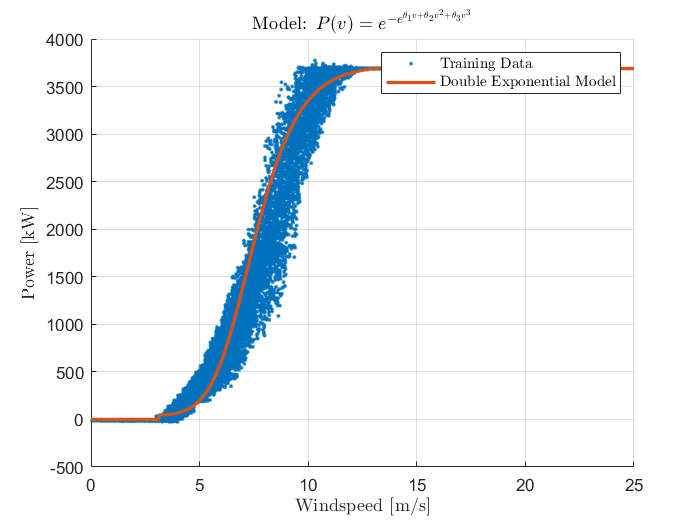

windspeedGrid = [0 : density : 25 ]';

figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
hold on;
plot(windspeedGrid, doubleExponential_model(windspeedGrid, theta, cutoutDE, saturationValue, cutinDE, scale) ,"LineWidth", 2);
grid on;
title('Model: $P(v) = e^{-e^{\theta_1 v + \theta_2 v^2 + \theta_3 v^3}}$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Power [kW]', "Interpreter", 'latex');
legend("Training Data", "Double Exponential Model", "Interpreter", 'latex');

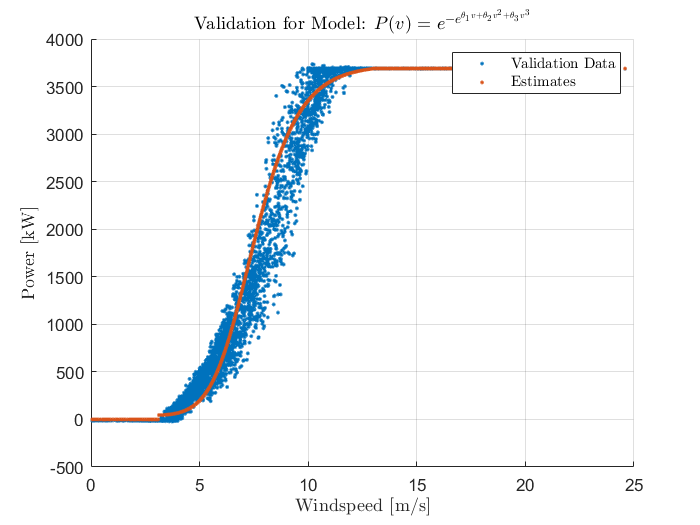

Y_Hat_validation = doubleExponential_model(validationSet.windspeed, theta, cutoutDE, saturationValue, cutinDE, scale);

figure;
scatter(validationSet.windspeed, validationSet.power, '.');
hold on;
scatter(validationSet.windspeed, Y_Hat_validation ,'.');
grid on;
title('Validation for Model: $P(v) = e^{-e^{\theta_1 v + \theta_2 v^2 + \theta_3 v^3}}$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Power [kW]', "Interpreter", 'latex');
legend("Validation Data", "Estimates", "Interpreter", 'latex');

Goodness of fit:

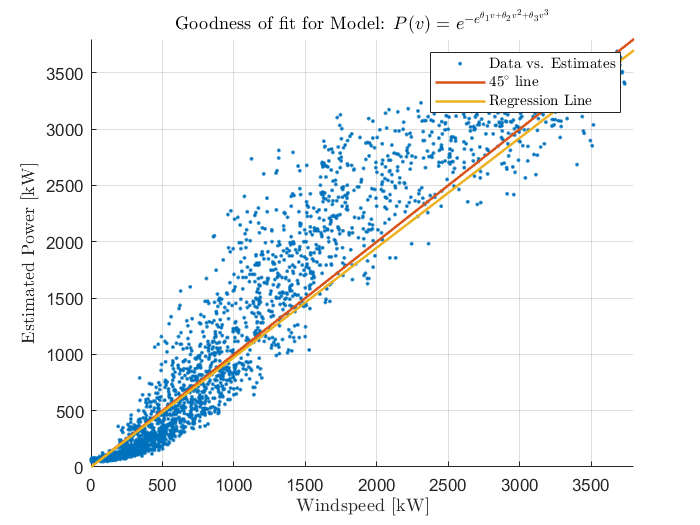

thetaGOF = lscov(Y_Hat_validation, validationSet.power);

figure;
scatter(validationSet.power, Y_Hat_validation, '.');
grid on;
hold on;
plot([0, 3800], [0,3800], 'LineWidth', 1.5);
plot([0, 3800], [0,thetaGOF * 3800], 'LineWidth', 1.5);
axis([0, 3800, 0, 3800]);
title('Goodness of fit for Model: $P(v) = e^{-e^{\theta_1 v + \theta_2 v^2 + \theta_3 v^3}}$', 'Interpreter', 'latex');
xlabel('Windspeed [kW]', "Interpreter", 'latex');
ylabel('Estimated Power [kW]', "Interpreter", 'latex');
legend("Data vs. Estimates", "$45^{\circ}$ line", "Regression Line", "Interpreter", 'latex');

doubleExponentialModel.parameters = theta;
doubleExponentialModel.standardDeviation = sigma;

doubleExponentialModel.SSR = sum((datainrange.power - Y_Hat).^2);
doubleExponentialModel.MSE = doubleExponentialModel.SSR / length(Y_Hat);

doubleExponentialModel.ValidationSSR = sum((validationSet.power - Y_Hat_validation).^2);
doubleExponentialModel.ValidationMSE = doubleExponentialModel.ValidationSSR / length(Y_Hat_validation);

doubleExponentialModel.WMAPE = sum(abs(validationSet.power - Y_Hat_validation)) / sum(abs(validationSet.power));
doubleExponentialModel.NRMSE = sqrt(doubleExponentialModel.ValidationMSE / (max(validationSet.power) - min(validationSet.power)));

## Funzione Logistica

La funzione logistica ha la caratteristica forma a sigmoide simile alla forma della curva di potenza da modellizzare:


$$P\left(v\right)=\frac{\theta_1 }{1+\theta_2 e^{-\theta_3 v} }$$


E' un modello non linrare, quindi va applicato un algoritmo iterativo come quello di Gauss-Newton con variante di Levenberg-Marquardt siccome le matrici appaiono singolari. (Non ho trovato un modo di aggiungerlo o specificarla, allora ho trovato un compromesso dato dal fatto che avevo una buona inizializzazione dal lavoro fatto dall'algoritmo di discesa del gradiente su Python).

Il fattore di Levenberg-Marquardt $\lambda$ (`dampingLM`) determina il comportamento dell'algoritmo. Un valore ridotto corrisponde ad un comportamento simile al metodo di Gauss-Newton, mentre un valore elevato corrisponde a un comportamento simile al metodo di discesa del gradiente.

Qui viene usato un fattore moltiplicativo di aggiornamento $\nu \;$(`dampingUpdate`). Data un iterazione, si valuta quale smorzamento tra $\lambda \;$e $\lambda \;/\nu \;$ produce un miglioramento della funzione di costo.

initialization = [saturationValue, 6.8820e4 , 1.74]';
theta_k = initialization;
iterations = 150;
normalization_factor = 1 / max(trainingSet.windspeed);
normalized_power = normalization_factor * trainingSet.power;
model_order = length(theta_k);
dampingLM = 8e-6;
dampingUpdate = 3;

cost_history = [sum(( trainingSet.power - logistic(trainingSet.windspeed, theta_k) ).^2) / length(trainingSet.power)];

for i = 1 : iterations
    [phi_1, phi_2, phi_3] = gradient_logistic(trainingSet.windspeed, theta_k);
    PHI_k = [phi_1, phi_2, phi_3];
    Y_tilde = normalized_power - normalization_factor * logistic(trainingSet.windspeed, theta_k);
    
    theta_tilde = inv( PHI_k' * PHI_k + dampingLM * eye(model_order) ) * (PHI_k' * Y_tilde);
    theta_tilde2 = inv( PHI_k' * PHI_k + (dampingLM/dampingUpdate) * eye(model_order) ) * (PHI_k' * Y_tilde);
    cost1 = sum((trainingSet.power - logistic(trainingSet.windspeed, theta_k + theta_tilde)).^2) / length(trainingSet.power) ;
    cost2 = sum((trainingSet.power - logistic(trainingSet.windspeed, theta_k + theta_tilde2)).^2) / length(trainingSet.power) ;
    
    if(cost1 > cost2)
        dampingLM = dampingLM/dampingUpdate;
        theta_tilde = theta_tilde2;
        cost_history = [cost_history; cost2];
    else
        cost_history = [cost_history; cost1];
    end
    
    theta_k = theta_k + theta_tilde;
end

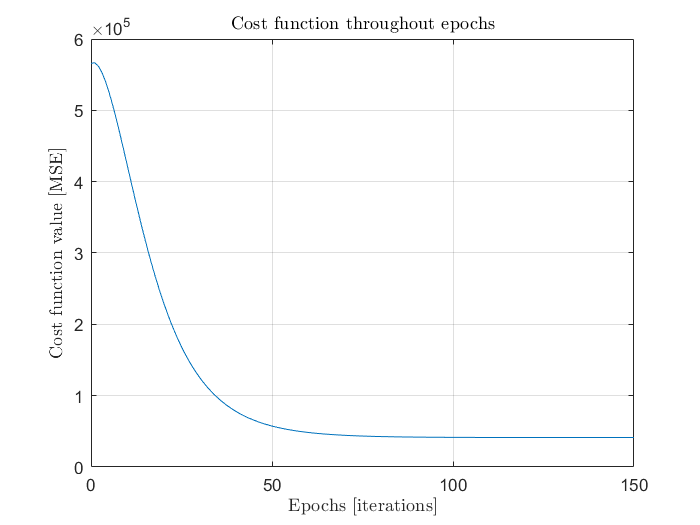

figure;
plot([0:iterations]', cost_history);
grid on;
title('Cost function throughout epochs', 'Interpreter', 'latex');
xlabel('Epochs [iterations]', "Interpreter", 'latex');
ylabel('Cost function value [MSE]', "Interpreter", 'latex');

theta = theta_k;

Linearizzo attorno ai parametri $\hat{\theta \;}$ trovati così da poter trovare una stima approssimata della variaza dei parametri dopo aver trovato una stima della variaza dell'errore.

[phi_1, phi_2, phi_3] = gradient_logistic(trainingSet.windspeed, theta_k);
PHI_k = [phi_1, phi_2, phi_3];
sigma_hat = (1/(length(Y_Hat) - length(theta))) * sum( (trainingSet.power - logistic(trainingSet.windspeed, theta)).^2);

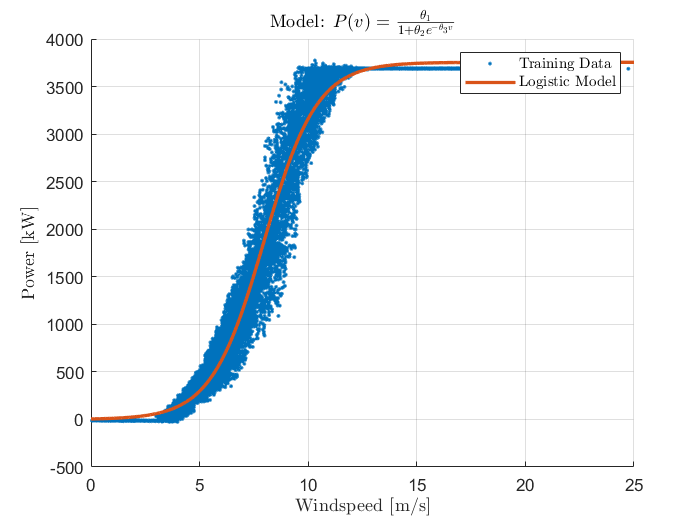

windspeedGrid = [0:0.01:25];
figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
hold on;
plot(windspeedGrid, logistic(windspeedGrid, theta), 'LineWidth', 2);
grid on;
title('Model: $P(v) = \frac{\theta_1}{1 + \theta_2 e^{- \theta_3 v}}$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Power [kW]', "Interpreter", 'latex');
legend('Training Data', 'Logistic Model', "Interpreter", 'latex');

Previsione sui dati di validazione:

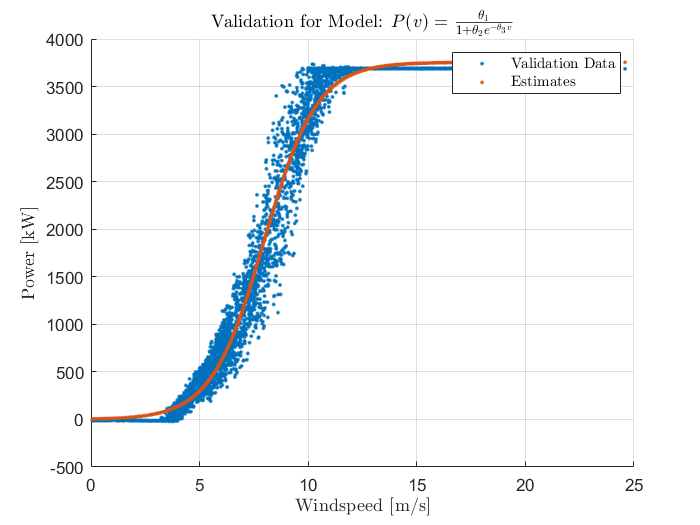

Y_Hat_validation = logistic(validationSet.windspeed, theta);

figure;
scatter(validationSet.windspeed, validationSet.power, '.');
hold on;
scatter(validationSet.windspeed, Y_Hat_validation, '.');
grid on;
title('Validation for Model: $P(v) = \frac{\theta_1}{1 + \theta_2 e^{- \theta_3 v}}$', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Power [kW]', "Interpreter", 'latex');
legend('Validation Data', 'Estimates', "Interpreter", 'latex');

Goodness of fit:

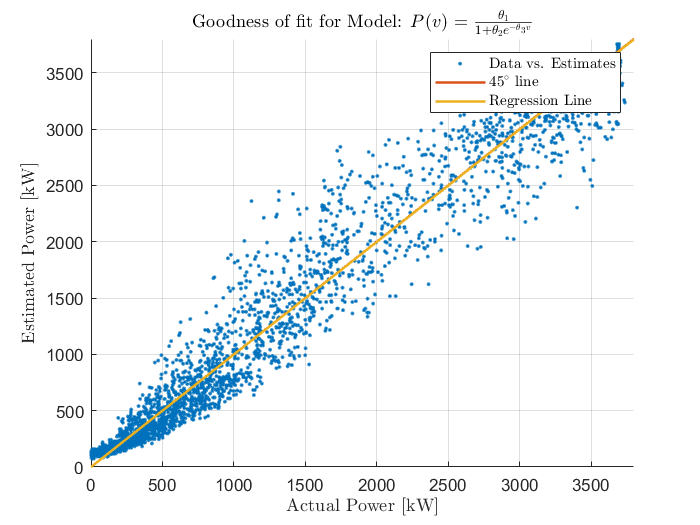

thetaGOF = lscov(Y_Hat_validation, validationSet.power);
figure;
scatter(validationSet.power, Y_Hat_validation, '.');
grid on;
hold on;
plot([0, 3800], [0,3800], 'LineWidth', 1.5);
plot([0, 3800], [0, thetaGOF * 3800], 'LineWidth', 1.5);
axis([0, 3800, 0, 3800]);
title('Goodness of fit for Model: $P(v) = \frac{\theta_1}{1 + \theta_2 e^{- \theta_3 v}}$', 'Interpreter', 'latex');
xlabel('Actual Power [kW]', "Interpreter", 'latex');
ylabel('Estimated Power [kW]', "Interpreter", 'latex');
legend("Data vs. Estimates", "$45^{\circ}$ line", "Regression Line", "Interpreter", 'latex');

Aggiungo ora i parametri e le metriche alla struttura:

logisticModel.parameters = theta;
logisticModel.standardDeviation = sqrt(diag(sigma_hat * inv(PHI_k' * PHI_k + 11e-5 * eye(model_order))));

logisticModel.MSE = (1/length(Y_Hat)) * sum( (trainingSet.power - logistic(trainingSet.windspeed, theta)).^2 );
logisticModel.SSR = sum( (trainingSet.power - logistic(trainingSet.windspeed, theta)).^2 );

logisticModel.ValidationSSR = sum((validationSet.power - Y_Hat_validation).^2);
logisticModel.ValidationMSE = logisticModel.ValidationSSR / length(Y_Hat_validation);

logisticModel.WMAPE = sum(abs(validationSet.power - Y_Hat_validation)) / sum(abs(validationSet.power));
logisticModel.NRMSE = sqrt(logisticModel.ValidationMSE / (max(validationSet.power) - min(validationSet.power)));

Confronto il modello logistico fatto con l'algoritmo Levenberg-Marquardt implementato a mano con uno che utilizza le funzioni di libreria.

inLineCostFunction = @(x) (trainingSet.power - logistic(trainingSet.windspeed, x));
theta = lsqnonlin(inLineCostFunction, initialization);


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


La curva individuata è la stessa dell'algoritmo Levenberg Marquardt, con gli stessi identici parametri.

### Multilayer Perceptron Neural Network

Dal teorema di Cybenko, una MLPNN a due strati è un approssimatore universale, quindi è possibile trovare una combinazione di numero di neuroni che possa approssimare con precisione arbitraria una qualsiasi funzione continua.

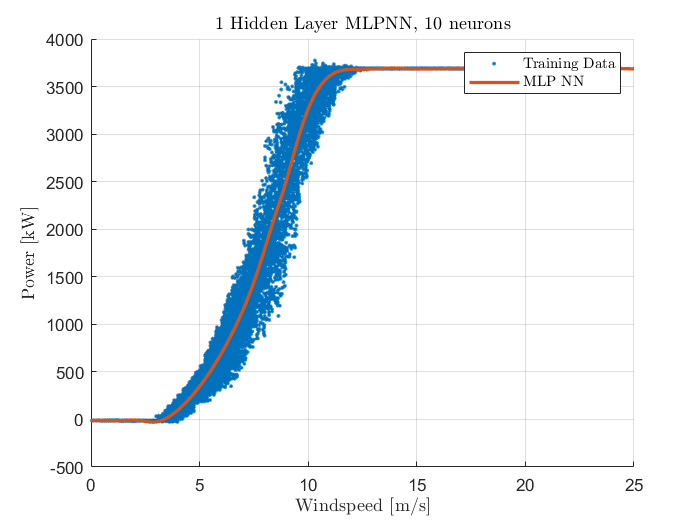

Y_Hat = multilayerPerceptronNeuralNetwork10(trainingSet.windspeed);
Y_Hat_validation = multilayerPerceptronNeuralNetwork10(validationSet.windspeed);

figure;
scatter(trainingSet.windspeed, trainingSet.power, '.');
hold on;
plot(windspeedGrid, multilayerPerceptronNeuralNetwork10(windspeedGrid'), 'LineWidth', 2);
grid on;
title('1 Hidden Layer MLPNN, 10 neurons', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Power [kW]', "Interpreter", 'latex');
legend("Training Data", "MLP NN", "Interpreter", 'latex');

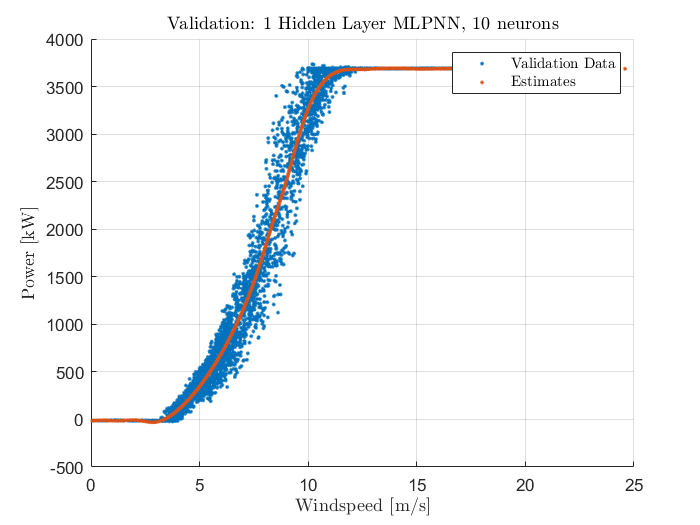


figure;
scatter(validationSet.windspeed, validationSet.power, '.');
hold on;
scatter(validationSet.windspeed, Y_Hat_validation, '.');
grid on;
title('Validation: 1 Hidden Layer MLPNN, 10 neurons', 'Interpreter', 'latex');
xlabel('Windspeed [m/s]', "Interpreter", 'latex');
ylabel('Power [kW]', "Interpreter", 'latex');
legend("Validation Data", "Estimates", "Interpreter", 'latex');

Goodness of fit:

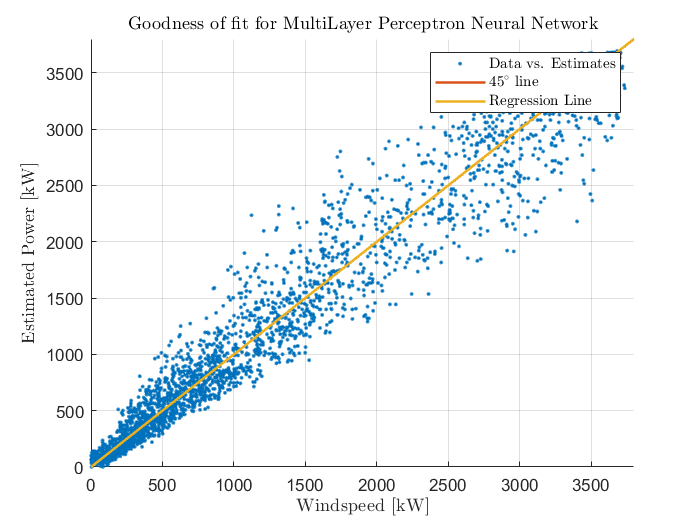

thetaGOF = lscov(Y_Hat_validation, validationSet.power);

figure;
scatter(validationSet.power, Y_Hat_validation, '.');
grid on;
hold on;
plot([0, 3800], [0,3800], 'LineWidth', 1.5);
plot([0, 3800], [0,thetaGOF * 3800], 'LineWidth', 1.5);
axis([0, 3800, 0, 3800]);
title('Goodness of fit for MultiLayer Perceptron Neural Network', 'Interpreter', 'latex');
xlabel('Windspeed [kW]', "Interpreter", 'latex');
ylabel('Estimated Power [kW]', "Interpreter", 'latex');
legend("Data vs. Estimates", "$45^{\circ}$ line", "Regression Line", "Interpreter", 'latex');

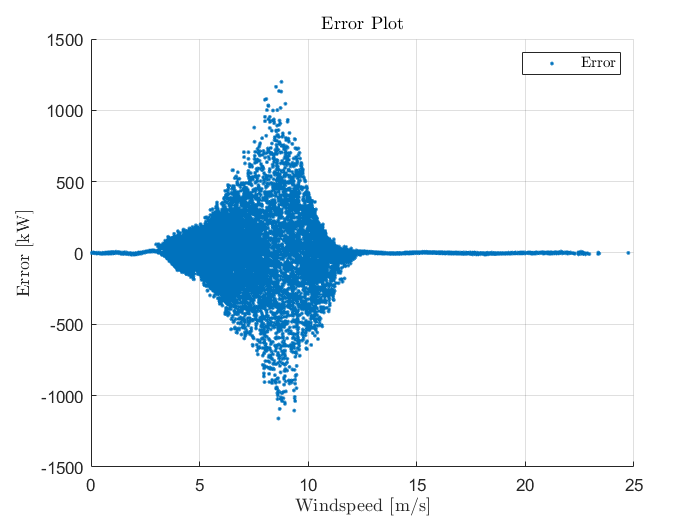

figure;
scatter(trainingSet.windspeed, (trainingSet.power - Y_Hat), '.');
grid on;
title('Error Plot', 'Interpreter',"latex");
xlabel('Windspeed [m/s]', 'Interpreter', 'latex');
ylabel('Error [kW]', 'Interpreter',"latex");
legend("Error", "Interpreter", 'latex');

MLPNN.SSR = sum((trainingSet.power - Y_Hat).^2);
MLPNN.ValidationSSR = sum((validationSet.power - Y_Hat_validation).^2);

MLPNN.WMAPE = sum(abs(validationSet.power - Y_Hat_validation)) / sum(abs(validationSet.power));
MLPNN.NRMSE = sqrt(logisticModel.ValidationMSE / (max(validationSet.power) - min(validationSet.power)));